 y' = 2x + 1, y(0) = 0

% Define the ODE and its initial condition
dydx = @(x, y) 2*x + 1;
y0 = 0;

% Define the exact solution
y_exact = @(x) x.*(x+1);

% Define the step size and the range of x values
h = 0.1;
x_start = 0;
x_end = 10000;
tspan = x_start:h:x_end;


% Initialize the variables for the Adams-Bashforth method
y_AB = [y0, y_exact(h)];

% Initialize the variables for the Adams-Moulton method
y_AM = y_AB;

% Initialize the time variable
tic;

% Apply the multiple-step method using Adams-Bashforth and Adams-Moulton methods
%for x = x_start+2*h:h:x_end
%    % Adams-Bashforth method
%    y_AB_new = y_AB(end) + (h/2)*(3*dydx(x, y_AB(end)) - dydx(x-h, y_AB(end-1)));
%    y_AB = [y_AB, y_AB_new];
%end

[t_ab, y_ab] = adams_bashforth(dydx, y0, tspan, h);

% Calculate the time taken for the calculations
time_AB = toc * 10000;

tic;

%for x = x_start+2*h:h:x_end
%    % Adams-Moulton method
%    y_AM_new = y_AM(end) + (h/2)*(dydx(x+h, y_AM(end)) + dydx(x, y_AM(end-1)));
%    y_AM_new = y_AM(end) + (h/2)*(dydx(x+h, y_AM_new) + dydx(x, y_AM(end)));
%    y_AM = [y_AM, y_AM_new];
%end

[t_am, y_am] = adams_moulton(dydx, y0, tspan, h);

% Calculate the time taken for the calculations
time_AM = toc * 1000;

% Calculate the exact solution for the range of x values
x_values = tspan;
y_exact_values = y_exact(x_values);

% Calculate the errors for the Adams-Bashforth and Adams-Moulton methods
error_ab = abs(y_ab' - y_exact_values);
error_am = abs(y_am' - y_exact_values);

% Calculate the time taken by each method
%time_ab = sum(t_ab);
%time_am = sum(t_am);

% Error per
per_error_arr_ab = abs(error_ab ./ y_exact_values * 100)

per_error_arr_ab =        NaN    9.0909    8.3333    5.1282    3.5714    2.6667    2.0833    1.6807    1.3889    1.1696    1.0000    0.8658    0.7576    0.6689    0.5952    0.5333    0.4808    0.4357    0.3968    0.3630    0.3333    0.3072    0.2841    0.2635    0.2451    0.2286    0.2137    0.2002    0.1880    0.1768    0.1667    0.1574    0.1488    0.1409    0.1337    0.1270    0.1208    0.1150    0.1096    0.1047    0.1000    0.0956    0.0916    0.0878    0.0842    0.0808    0.0776    0.0747    0.0718    0.0692


per_error_arr_am = abs(error_am ./ y_exact_values * 100)

per_error_arr_am =        NaN    9.0909    8.3333    5.1282    3.5714    2.6667    2.0833    1.6807    1.3889    1.1696    1.0000    0.8658    0.7576    0.6689    0.5952    0.5333    0.4808    0.4357    0.3968    0.3630    0.3333    0.3072    0.2841    0.2635    0.2451    0.2286    0.2137    0.2002    0.1880    0.1768    0.1667    0.1574    0.1488    0.1409    0.1337    0.1270    0.1208    0.1150    0.1096    0.1047    0.1000    0.0956    0.0916    0.0878    0.0842    0.0808    0.0776    0.0747    0.0718    0.0692



% Mean Error Per
mean_error_ab = mean(per_error_arr_ab(2:end))

mean_error_ab = 4.9486e-04

mean_error_am = mean(per_error_arr_am(2:end))

mean_error_am = 4.9486e-04

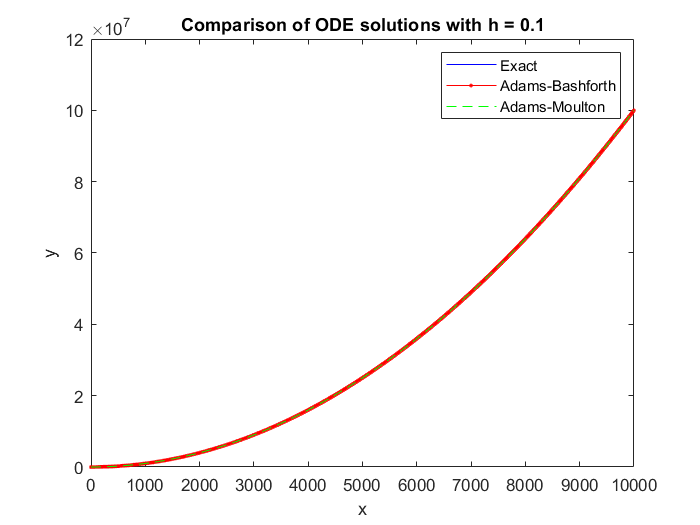




% Plot the results
plot(x_values, y_exact_values, 'b-', x_values, y_ab, 'r.-', x_values, y_am, 'g--');
legend('Exact', 'Adams-Bashforth', 'Adams-Moulton');
xlabel('x');
ylabel('y');
title(sprintf('Comparison of ODE solutions with h = %0.1f', h));


% Print the time taken for each method
fprintf('Time taken for Adams-Bashforth method: %f seconds\n', time_AB);

Time taken for Adams-Bashforth method: 201.472000 seconds


fprintf('Time taken for Adams-Moulton method: %f seconds\n', time_AM);

Time taken for Adams-Moulton method: 26.607700 seconds


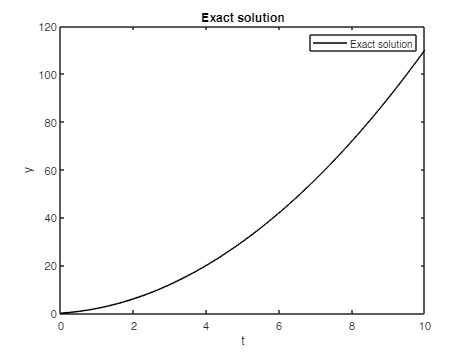

figure;
plot(x_values, y_exact_values, 'black-');
xlabel('t');
ylabel('y');
legend('Exact solution');
title('Exact solution');

function [t, y] = adams_bashforth(f, y0, tspan, h)
% Solve an ODE using the Adams-Bashforth method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Bashforth method to compute the remaining values of y
for i = 3:length(t)-1
    y(i+1,:) = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
end
end


function [t, y] = adams_moulton(f, y0, tspan, h)
% Solve an ODE using the Adams-Moulton method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Moulton method to compute the remaining values of y
for i = 3:length(t)-1
    % Adams-Bashforth Order 3 (yn+3)
    y_predictor = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
    % Corrector using Adams-Moulton method of order 3 (yn+2)
    y_corrector = y(i,:) + (h/12)*(5*f(t(i+1), y_predictor) + 8*f(t(i), y(i,:)) - f(t(i-1), y(i-1,:)))';
    y(i+1,:) = y_corrector;
end

end